# Van der Pol closed-loop dynamics: held-out evaluation

This Live Script evaluates saved publication models through the current BANFF architecture. It reports the same task-level statistics and diagnostic plot families as the older task-specific implementation.

clearvars; close all; clc;

## Locate the publication code

evaluation_directory = fileparts(mfilename('fullpath'));
repository_root = fileparts(evaluation_directory);
addpath(repository_root, evaluation_directory);

## Choose the saved experiment family

Use the same profile and scientific overrides that were used for training.

seeds = 1:3;
profile = "main";            % main, full_rank, spsa, or neuron_sweep
overrides = struct();         % e.g. struct('N_hidden',8000) for neuron_sweep

## Choose display and export behaviour

display_options = struct();
display_options.representative_seed_index = 1;
display_options.representative_initial_condition = 1;
display_options.replay_static_spikes = true;
display_options.save_figures = false;
display_options.output_directory = fullfile(repository_root, ...
    'outputs', 'evaluation', 'vanderpol');

## Run held-out testing, statistics, seed audit, and plots


BANFF held-out test evaluation: vanderpol (main profile)
Seeds: [1 2 3]

Per-seed held-out test results
    Seed    PhaseDistance    BestValidationPhaseDistance    TestInitialConditions
    ____    _____________    ___________________________    _____________________

     1        0.046255                0.022488                        5          
     2         0.13411                 0.14327                        5          
     3         0.31492                  0.3201                        5          

Across-seed mean and sample SD
               Metric                 Mean      SampleSD    FiniteN
    _____________________________    _______    ________    _______

    "PhaseDistance"                   0.165

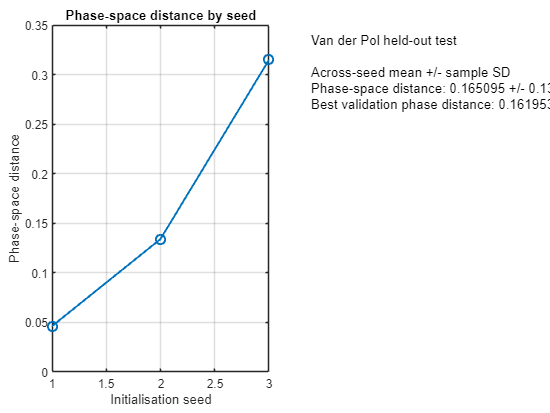

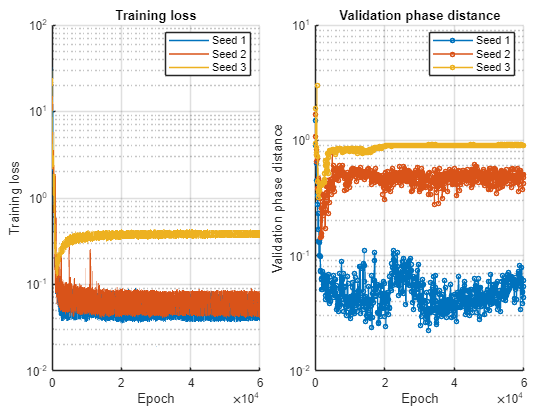

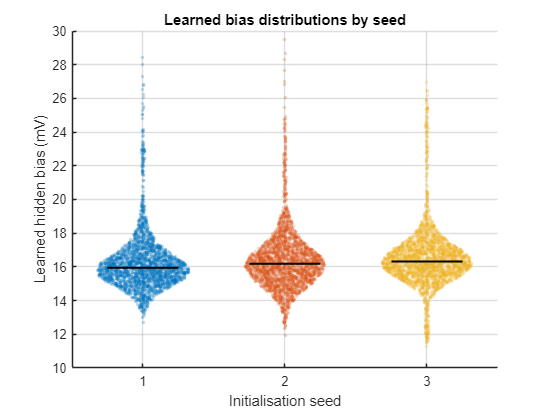

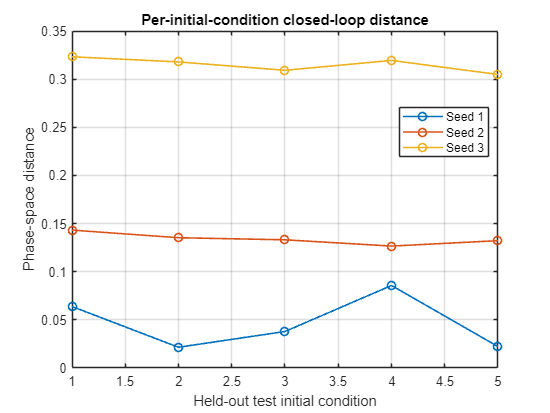

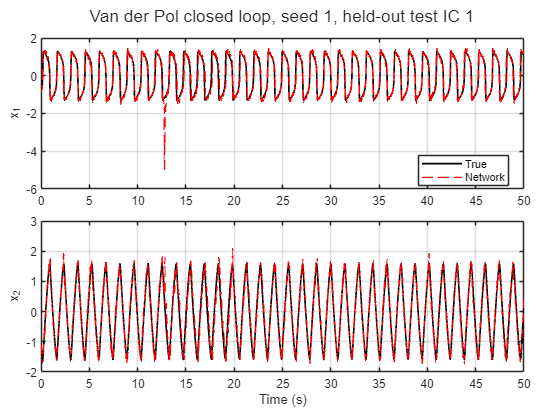

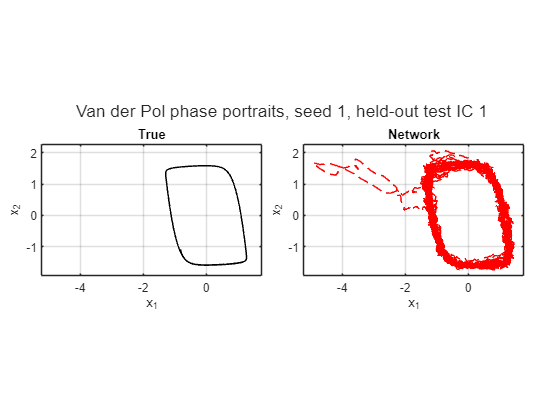

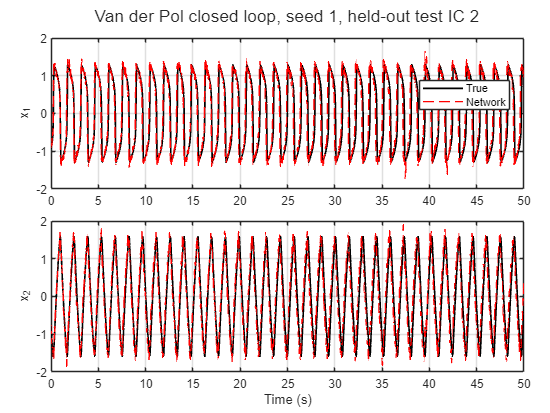

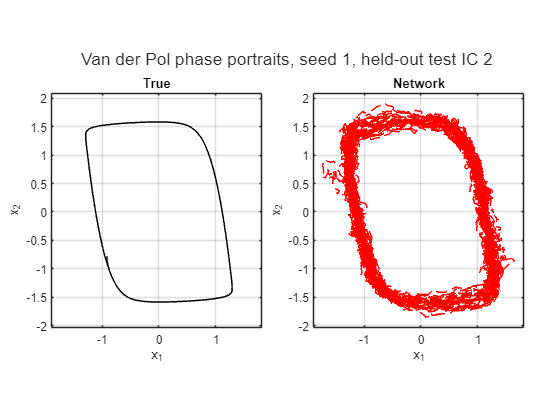

Dynamics seed 1: 26.87% active, 73.13% silent neurons; 474374 spikes.
Inverse-ISI distribution pools 2125561 within-trajectory intervals from all 32000 neurons and all 5 held-out test initial conditions.


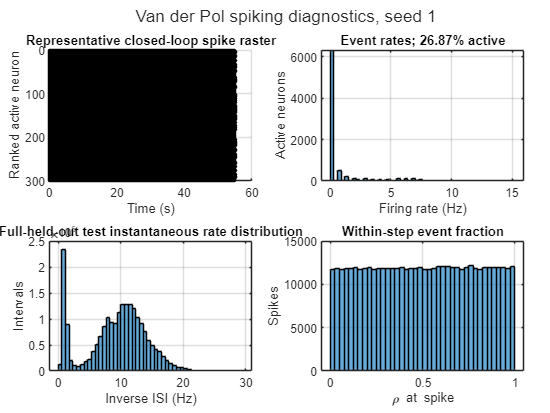

Dynamics seed 2: 9.82% active, 90.18% silent neurons; 550204 spikes.
Inverse-ISI distribution pools 2484955 within-trajectory intervals from all 32000 neurons and all 5 held-out test initial conditions.


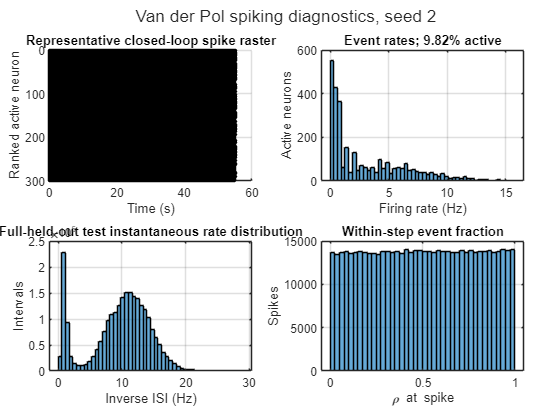

Dynamics seed 3: 14.12% active, 85.88% silent neurons; 586277 spikes.
Inverse-ISI distribution pools 2625216 within-trajectory intervals from all 32000 neurons and all 5 held-out test initial conditions.


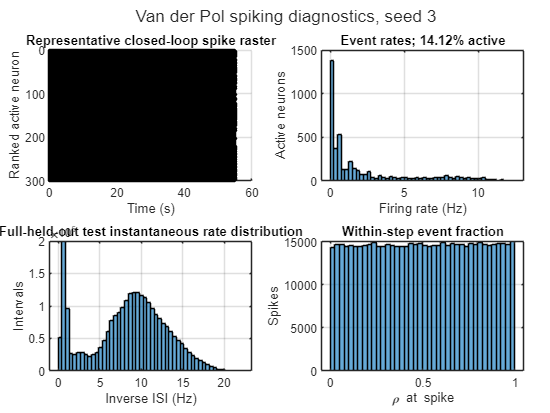

Seed 1 exact full-held-out test DS current magnitudes (scored interval; warmup excluded)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    ____________________    _______________    __________________    ______________________

    "Untrained"            0                  0           

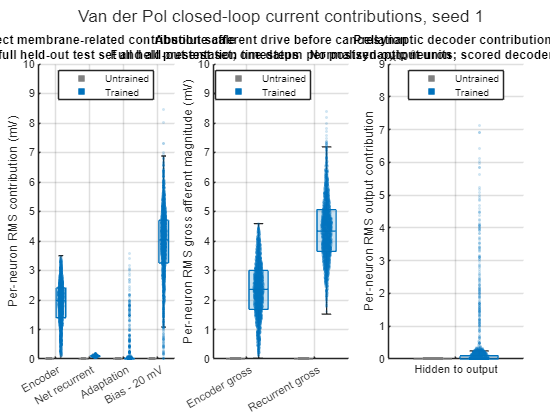

Seed 2 exact full-held-out test DS current magnitudes (scored interval; warmup excluded)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    ____________________    _______________    __________________    ______________________

    "Untrained"            0                 0            

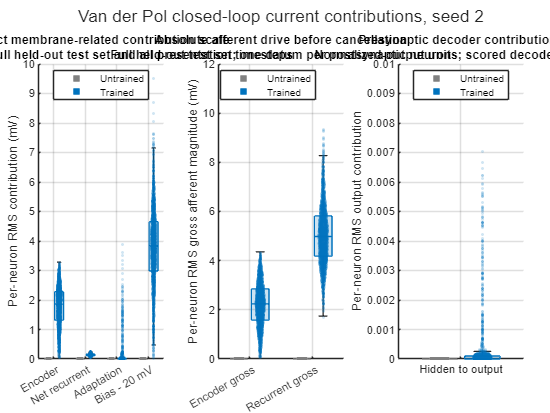

Seed 3 exact full-held-out test DS current magnitudes (scored interval; warmup excluded)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    ____________________    _______________    __________________    ______________________

    "Untrained"            0                  0           

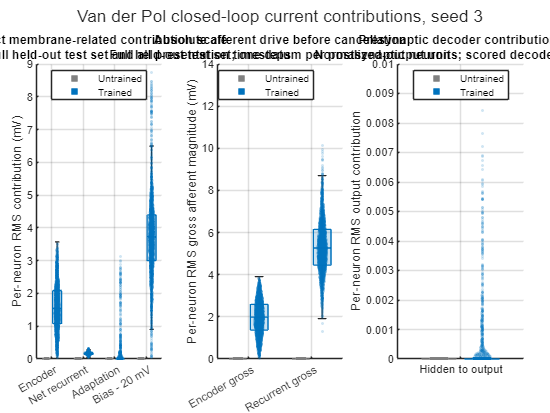

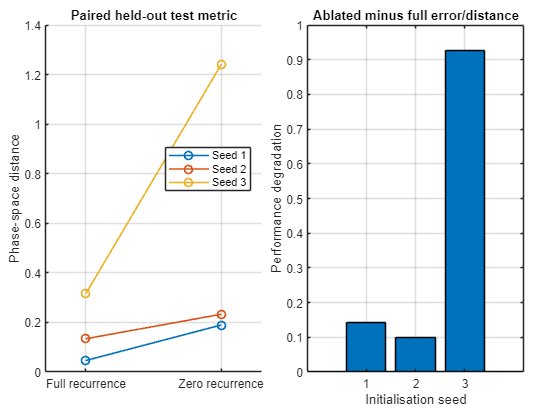

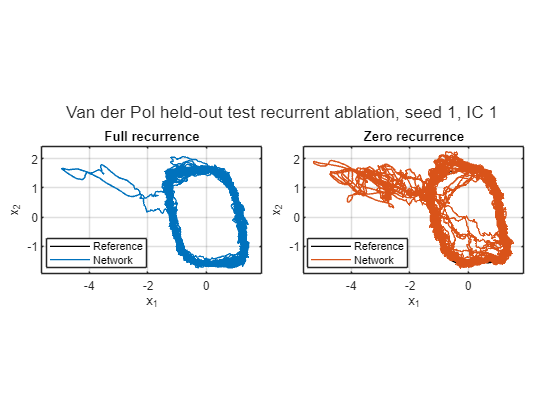

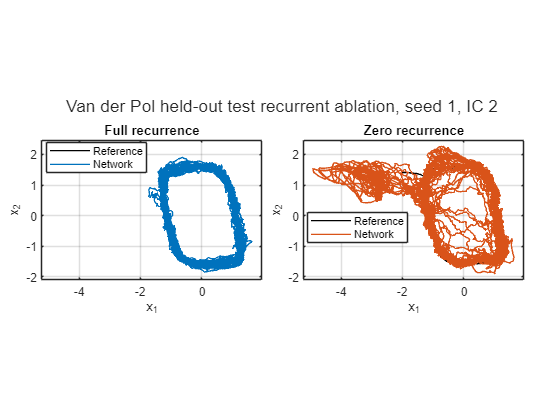

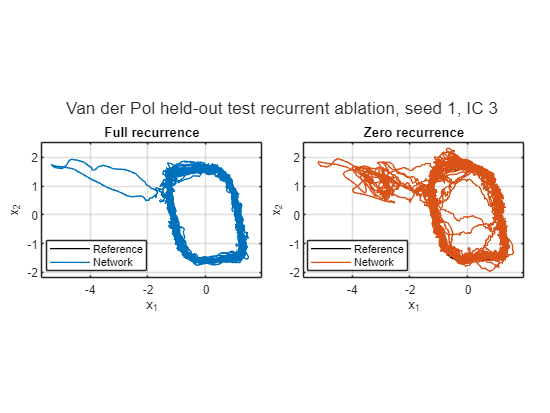

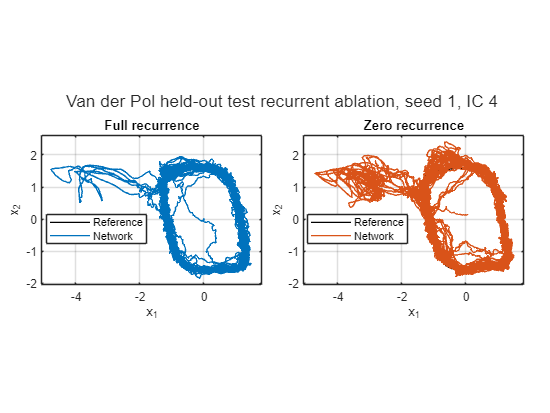

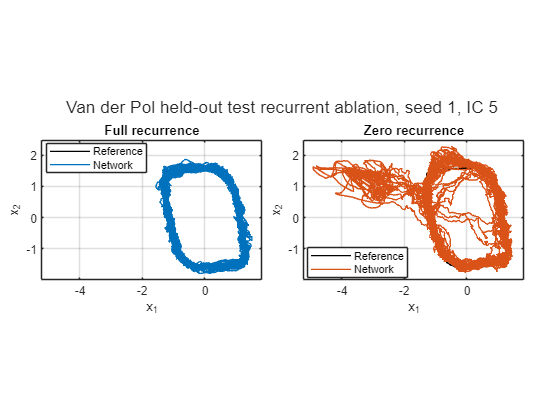

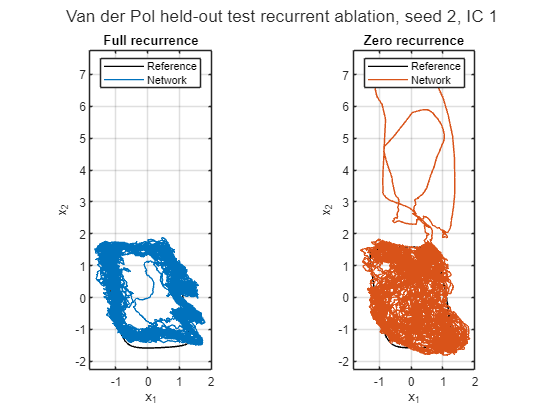

report = banff_evaluate_task("vanderpol", seeds, profile, overrides, display_options);

## Machine-readable results

report.seed_table

ans = 3×4 table
    Seed    PhaseDistance    BestValidationPhaseDistance    TestInitialConditions
    ____    _____________    ___________________________    _____________________

     1        0.046255                0.022488                        5          
     2         0.13411                 0.14327                        5          
     3         0.31492                  0.3201                        5          


report.summary_table

ans = 2×4 table
               Metric                 Mean      SampleSD    FiniteN
    _____________________________    _______    ________    _______

    "PhaseDistance"                   0.1651    0.13699        3   
    "BestValidationPhaseDistance"    0.16195    0.14968        3   


report.network_seed_audit

ans = 3×4 table
    Seed                                                               ModelFile                                                                                         CheckpointHash                                                    FixedNetworkProbeHash                       
    ____    _______________________________________________________________________________________________________________________________    __________________________________________________________________    __________________________________________________________________

     1      "/home/kai.mason/Documents/BANFF_SNN_pub/outputs/models/vanderpol_eprop_low_rank_hard_spike_N32000_cfgc9a77f754d21_seed001.mat"    "a19ecb5efe8bb6862db1c5f5abefa7d3feecd99fe1d8ba64c2b06f7e731fe1b5"    "8a03c9aaadeea75965e2aaf6a814128d01ed96aed177397bd05985505402d3f2"
     2 